# Neural Networks Part 2

## Running the neural network for the ovarian cancer data set

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. Each iteraction where we run a single round of forward and backward propagation is called an **epoch. **This is another hyperparameter that we can tune to assess model performance. 

The `SNN` function for the shallow neural network is modularized to the three steps we performed: forward propagation, evaluating the cost, and back propagation. The values from forward propagation are stored in a `structure` data type called `cache. `Similarly, the values from back prop are stored in the `backwardCache` variable. Further documentation is included in the `SNN` function. 

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the ovarian cancer dataset:

clear all; rng('default');

[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

numOfActiveNodes = 2;
alpha = 0.05;
epoch = 500;
actFnc = 'Sigmoid';
randomstate = true;

model = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, actFnc, randomstate);

### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

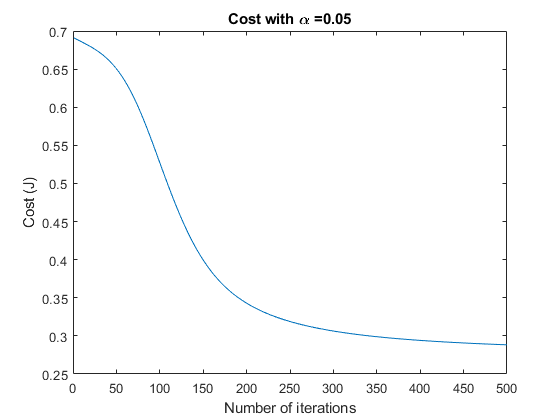

figure
plot(1:length(model.J), model.J);
title(strcat('Cost with \alpha = ', string(alpha)));
xlabel('Number of iterations');
ylabel('Cost (J)');

As you can see, while it appears that the model is approaches a minimum cost value of 0.28 when the learning rate is 0.05.

### Assessing model accuracy

#### Hold out accuracy

Next, let's use the test set to come up with a prediction. To do that using our neural network, we can use the `predict `function, which takes the test data and outputs predictions for classification. 

ypred = predict(model, Xtest, Ytest, 'SNN');

Now that we have a prediction from our neural network, we can evaluate the model accuracy. Note that the values from `yred` are not necessarily 0 and 1. To transform our values back to our labels, we need to determine a decision boundary for classification. Let's use mean value of $y_{\textrm{pred}}$ as the decision boundary, where observations with a value greater than the $\textrm{mean}\left(y_{\textrm{pred}} \right)$ are assigned to be 1 (malignant). Otherwise, we'll assign that value to be 0 (benign). 

We'll also plot the confusion matrix and report the hold out accuracy using the `plotConfusionMatrix` code in the directory.

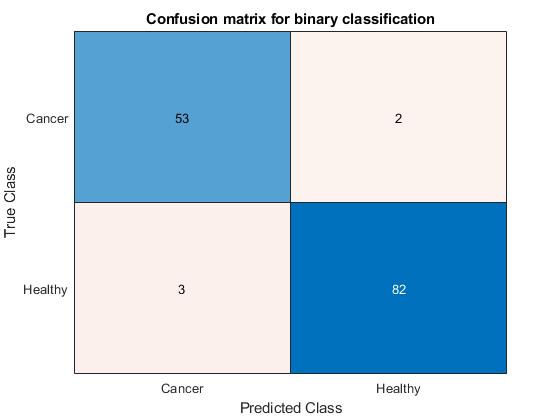

Summary = plotConfusionMatrix(Ytest, ypred);

disp(strcat('Hold-out malignant classification accuracy: ', string(Summary.Class1)))

Hold-out malignant classification accuracy:0.96364


disp(strcat('Hold-out benign classification accuracy: ', string(Summary.Class2)))

Hold-out benign classification accuracy:0.96471


disp(strcat('Hold-out average classification accuracy: ', string(Summary.Accuracy)))

Hold-out average classification accuracy:0.96429


#### Cross validation accuracy

Of course, the hold out accuracy itself is not necessarily the best measure to evaluate the neural network. Let's also run **10-fold cross validation** and see how our model does on average. The `crossValidate` function is used to compute k-fold cross validation with two classes 

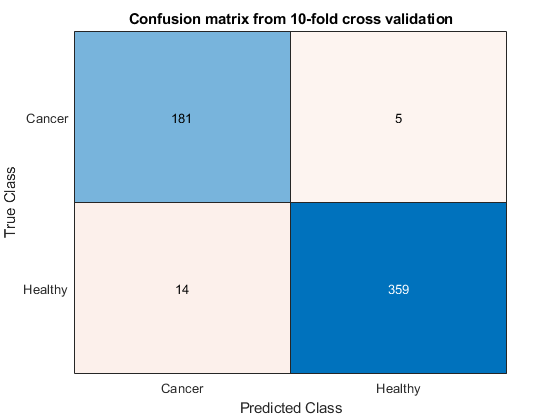

kfold = 10;
type  = 'SNN';
Summary = crossValidate(Xtrain, Ytrain, model, kfold, type);

disp(strcat('10-fold CV malignant classification accuracy: ', string(Summary.cancerAccuracy)))

10-fold CV malignant classification accuracy:0.92424


disp(strcat('10-fold CV benign classification accuracy: ', string(Summary.healthyAccuracy)))

10-fold CV benign classification accuracy:0.98536


disp(strcat('10-fold CV average classification accuracy: ', string(Summary.averageClassAccuracy)))

10-fold CV average classification accuracy:0.96591


## Issues in training neural networks

While neural networks are really popular for artificial intelligence research and applications, there are issues with training them. We'll discuss some of these issues in this section.

### Initializing values for w and b

Earlier, we initialized our values for w and b to be small random numbers. Is this the best choice for w and b? We discuss 2 alternative cases that are different from our random intiialization of small numbers: if w and b are all zeros and all ones.

#### Setting w and b to be all zeros

We'll go back to our synthetic dataset with 50 observations and 6 features and plot the results when w and b are all zero.

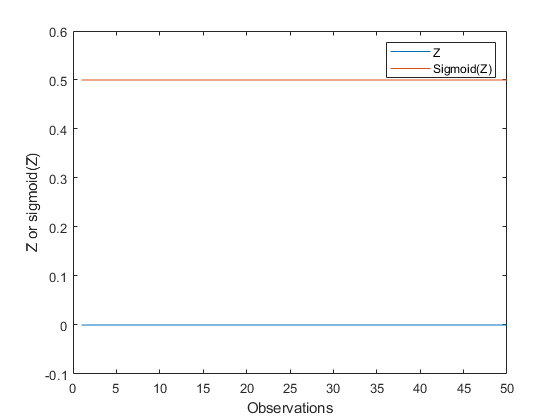

rng('default');

Xtrain = normrnd(0, 1, [50, 6]);

w = [0, 0, 0, 0, 0, 0];
b = zeros([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on;
plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
ylim([-0.1 0.6]);
xlabel('Observations');
ylabel('Z or sigmoid(Z)');

If the values are all zeros, the neural network stops learning the features - they will be stuck at Z = 0 and A = 0.5 during every iteration.

#### Setting w and b to be all ones

Let's see what happens when we set w and b to be all ones:

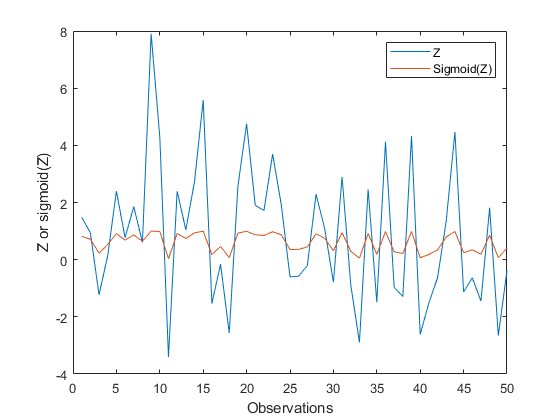

w = [1, 1, 1, 1, 1, 1];
b = ones([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on;
plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
xlabel('Observations');
ylabel('Z or sigmoid(Z)');

As you can see, our features (blue) end up being transformed to log-odds in the range [0, 1] (red) by the activation function. Thus, the neural network algorithm essentially becomes a logistic regression classifier when using the sigmoid activation function and the biases are all equal to 1.

#### Symmetry breaking

**Symmetry breaking** is a phenomenon where very small, random fluctuations in a system are able to influence the outcome. By randomly initializing w and b to be small random numbers, we don't break the algorithm from the beginning and we allow the neural network to approach a better solution through back propagation / gradient descent.

### Overfitting

Recall that our objective in machine learning is to build a model that balances the model's ability to minimize bias and variance. Neural networks are relatively complex models, and are susceptible to model overfitting - that is, they are susceptible to learning from noisy data. This is especially true when the number of predictors `p` is much greater than the number of observations `n`. 

To address this issue, regularization is usually imposed in the loss function to select the predictors that best explain the variance of the dataset. Thus, we reduce the amount of noise in the dataset, allowing the neural network to better capture the trends in the data. 

### Data scaling

It is good practice to standardize all the features to have a mean of zero and standard deviation of one. This ensures that the inputs are treated equally by the random starting weights.

### Multiple cost minima

The error function may not be convex -  in other words, there may be multiple minima that gradient descent can converge to. To try to get the best solution, different learning rates should be explored.

## Benchmarking against a logistic regression classifier

A neural network is a more flexible model compared to other models, in that it performs both linear and nonlinear transformations on the data. Let's see how well our shall model performs against a logistic regression classifier, a less flexible model that only performs nonlinear transformations on the dataset.  

### Logistic regression

Recall that the formulation for a logistic regression problem is 1) applying the sigmoid function to our linear equation $f\left(x\right)=X^T \beta$ to transform the values to log-odds, then 2) finding $\beta$ that maximizes the likelihood function. Thus the equation we're trying to solve for a logistic regression problem is:


$$f\left(x\right)=\frac{1}{1+e^{-X^T \beta } }$$


This logistic regression classifier will compute values using back propagation and gradient descent using the `logRegress` function. You don't need to worry about the implementation, but just note that gradient descent is a robust method for machine learning.

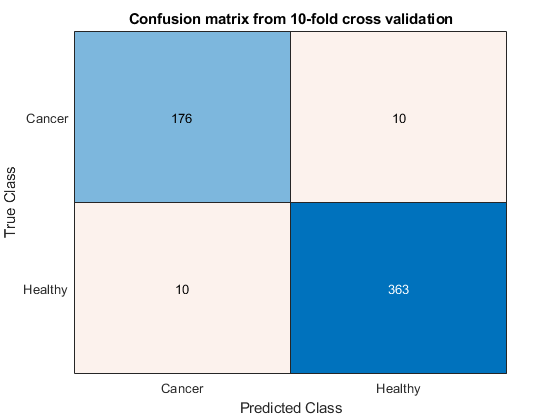

logisticCM = struct with fields:
                   kfold: 10
                      cm: [2×2 double]
            NormalizedCM: [2×2 double]
          cancerAccuracy: 0.9419
         healthyAccuracy: 0.9729
    averageClassAccuracy: 0.9641


clear all;
rng('default');

[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

theta = mnrfit(Xtrain, categorical(Ytrain));
logistic.theta = theta;

kfold = 10;
type = 'Logistic';

logisticCM = crossValidate(Xtrain, Ytrain, logistic, kfold, type)

disp(strcat('10-fold CV malignant classification accuracy: ', string(logisticCM.cancerAccuracy)))

10-fold CV malignant classification accuracy:0.9419


disp(strcat('10-fold CV benign classification accuracy: ', string(logisticCM.healthyAccuracy)))

10-fold CV benign classification accuracy:0.97293


disp(strcat('10-fold CV average classification accuracy: ', string(logisticCM.averageClassAccuracy)))

10-fold CV average classification accuracy:0.96412


### Shallow neural network

Let's re-train our neural network and compare the two results

nnCM = struct with fields:
                   kfold: 10
                      cm: [2×2 double]
            NormalizedCM: [2×2 double]
          cancerAccuracy: 0.9242
         healthyAccuracy: 0.9854
    averageClassAccuracy: 0.9659


clearvars -except logisticCM;
rng('default');

[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

numOfActiveNodes = 2;
alpha = 0.05;
epoch = 500;
actFnc = 'Sigmoid';
randomstate = true;

nn = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, actFnc, randomstate);
ypred = predict(nn, Xtest, Ytest, 'SNN');

kfold = 10;
type = 'SNN';
nnCM = crossValidate(Xtrain, Ytrain, nn, kfold, type)


disp(strcat('10-fold CV malignant classification accuracy: ', string(nnCM.cancerAccuracy)))

10-fold CV malignant classification accuracy:0.92424


disp(strcat('10-fold CV benign classification accuracy: ', string(nnCM.healthyAccuracy)))

10-fold CV benign classification accuracy:0.98536


disp(strcat('10-fold CV average classification accuracy: ', string(nnCM.averageClassAccuracy)))

10-fold CV average classification accuracy:0.96591


### Results

The shallow neural network slightly outperforms the logistic regression classifier, especially when the data is more complex.

## Summary

In this lecture, we trained a shallow neural network on breast cancer imaging data and evaluated its performance. Additionally, we discussed how training a neural network can be challenging, and some common pitfalls. Finally, we benchmarked the neural network against a logistic regression classifier, and found that the neural network outperformed the logistic regression classifier.

## Useful reading and references

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence.